## Q5b) Melbourne Street Modelling

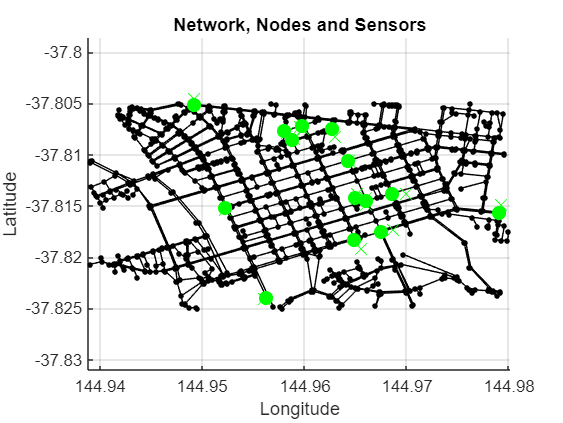

clear
close all
% load data
load_MPC_data % external script for clarity
Load_Melbourne_StData

% plot sensor locations
plot_q5_b

Building a regression model using `'fitnlm'`, centrality measures and three time steps of previous counts. 

% find centrality metric
% make a graph from edge and node data
G = graph(Melbourne_Edgelist.idx1, Melbourne_Edgelist.idx2);
G.Nodes = Melbourne_Node;

% getting centrality metrics
degreeCentrality = centrality(G, 'degree');
closenessCentrality = centrality(G, 'closeness');
betweennessCentrality = centrality(G, 'betweenness');
eigenvectorCentrality = centrality(G, 'eigenvector');
pageRankCentrality = centrality(G, 'pagerank');


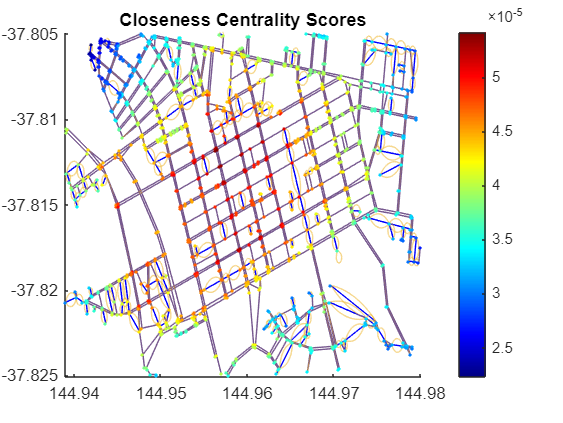

% Plot edges (adjacency matrix A)
figure;
hold on;

% Compute axis limits from node data
padding = 0.0001; % Add some padding to prevent clipping
x_min = min(Melbourne_Node.Long) - padding;
x_max = max(Melbourne_Node.Long) + padding;
y_min = min(Melbourne_Node.Lat) - padding;
y_max = max(Melbourne_Node.Lat) + padding;

% Lock axis limits before plotting
xlim([x_min, x_max]);
ylim([y_min, y_max]);

pos_table = [Melbourne_Node.Lat,Melbourne_Node.Long];
s = '-b.';
N = size(A, 2);
for i = 1:N
    for j = i+1:N
        if A(i, j) == 1
            % Extract edge positions
            xx = [Melbourne_Node.Long(i), Melbourne_Node.Long(j)];
            yy = [Melbourne_Node.Lat(i), Melbourne_Node.Lat(j)];
            % Plot the edge
            plot(xx, yy, '-b', 'LineWidth', 0.5); % Blue lines for edges
        end
    end
end
% Plot graph nodes
ucc = centrality(G,'closeness');
p = plot(G, 'XData', Melbourne_Node.Long, 'YData', Melbourne_Node.Lat, ...
    'NodeCData', ucc, 'MarkerSize', 1);
p.NodeCData = ucc;
colormap jet
colorbar
title('Closeness Centrality Scores')

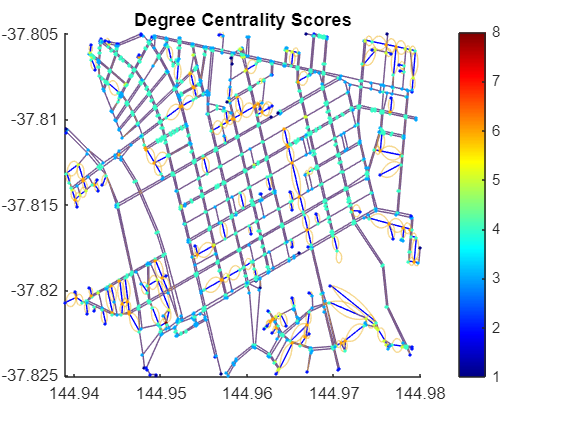

figure;
hold on;

% Compute axis limits from node data
padding = 0.0001; % Add some padding to prevent clipping
x_min = min(Melbourne_Node.Long) - padding;
x_max = max(Melbourne_Node.Long) + padding;
y_min = min(Melbourne_Node.Lat) - padding;
y_max = max(Melbourne_Node.Lat) + padding;

% Lock axis limits before plotting
xlim([x_min, x_max]);
ylim([y_min, y_max]);

pos_table = [Melbourne_Node.Lat,Melbourne_Node.Long];
s = '-b.';
N = size(A, 2);
for i = 1:N
    for j = i+1:N
        if A(i, j) == 1
            % Extract edge positions
            xx = [Melbourne_Node.Long(i), Melbourne_Node.Long(j)];
            yy = [Melbourne_Node.Lat(i), Melbourne_Node.Lat(j)];
            % Plot the edge
            plot(xx, yy, '-b', 'LineWidth', 0.5); % Blue lines for edges
        end
    end
end
ubc = centrality(G,'degree');
p = plot(G, 'XData', Melbourne_Node.Long, 'YData', Melbourne_Node.Lat, ...
    'NodeCData', ubc, 'MarkerSize', 1);
p.NodeCData = ubc;
colormap jet
colorbar
title('Degree Centrality Scores')

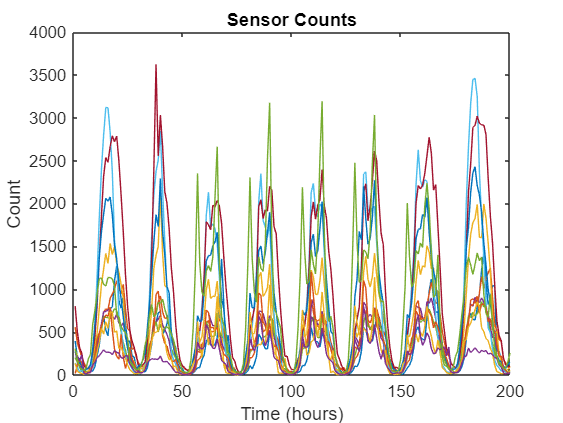

figure;
plot(sen_data.count(:,1:12))
title('Sensor Counts')
xlim([0 200]);
xlabel('Time (hours)');
ylabel('Count');

% legend(sen_data.name(:,1:12))

% get IDW predictions for all nodes
time_sim = 300;
predi = zeros(time_sim,height(G.Nodes));
tic
for i = 1:height(G.Nodes)
    for j = 1:time_sim
        % need to get distance between target node and sensor nodes
        predi(j,i) = IDWprediction(G, i, sen_data.count(j, :), sen_data.Node_idx);
    end
end
toc

Elapsed time is 140.249369 seconds.


n = length(sen_data.count(:,1));
train_p = 0.8

train_p = 0.8000

train_size = round(train_p * n);

model_fit = @(b, x) b(1).*x(:,1) + ... % degree centrality
    b(2).*x(:,2)... % closenessCentrality
    + b(3).*x(:,3)... % betweennessCentrality
    + b(4).*x(:,4)... % counts at previous time step
    + b(5).*x(:,5)... % counts two time steps ago
    + b(6).*x(:,6); % counts three time steps ago
beta0 = [0.001 1.8 0.001 1 1 1];
X = [degreeCentrality, closenessCentrality, betweennessCentrality, predi(120, :)', predi(119, :)', predi(118, :)'];% network-based parameters
mdl = fitnlm(X,predi(121, :)',model_fit,beta0)

mdl = Nonlinear regression model:
    y ~ b1*x1 + b2*x2 + b3*x3 + b4*x4 + b5*x5 + b6*x6

Estimated Coefficients:
           Estimate          SE          tStat        pValue   
          ___________    __________    _________    ___________

    b1        0.49632       0.13316       3.7272     0.00020239
    b2          31282    4.7098e-07    6.642e+10              0
    b3    -3.7779e-06    7.3137e-06     -0.51656        0.60556
    b4        0.89948      0.021995       40.895    6.3485e-232
    b5       0.026647     0.0044833       5.9437     3.6194e-09
    b6       -0.14881      0.006081      -24.472    3.6288e-108


Number of observations: 1241, Error degrees of freedom: 1236
Root Mean Squared Error: 4.92
R-Squared: 0.755,  Adjusted R-Squared 0.755

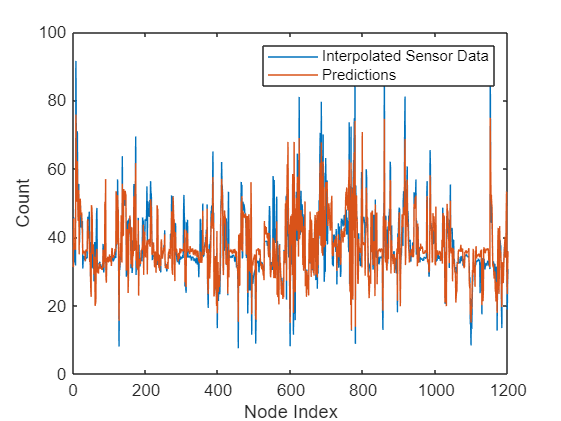


figure;
plot(predi(121, :)')
hold on
plot(mdl.Fitted)
xlabel('Node Index')
ylabel('Count')
xlim([0 1200]);
legend('Interpolated Sensor Data', 'Predictions');

% beta1 = mdl.Coefficients.Estimate
disp(mdl.RMSE);

    4.9224



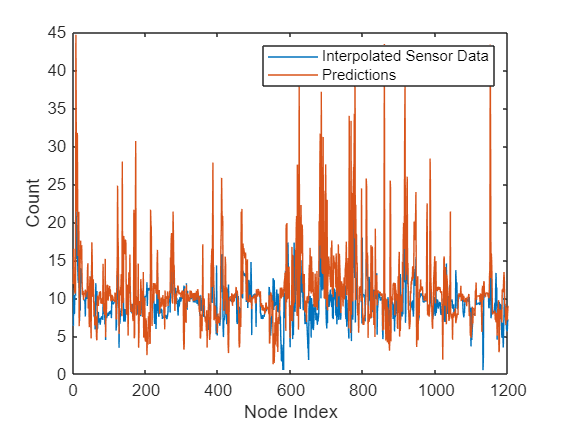


X_new = [degreeCentrality, closenessCentrality, betweennessCentrality, predi(123, :)', predi(122, :)', predi(121, :)'];
y_future_pred = predict(mdl, X_new); % Predict future counts
y_future_real = predi(124, :)';
figure;
plot(y_future_real)
hold on
plot(y_future_pred)
xlabel('Node Index')
ylabel('Count')
xlim([0 1200]);
legend('Interpolated Sensor Data', 'Predictions');

rmse = sqrt(mean((y_future_real - y_future_pred).^2)); % RMSE formula
disp(['RMSE: ', num2str(rmse)]);

RMSE: 3.9374


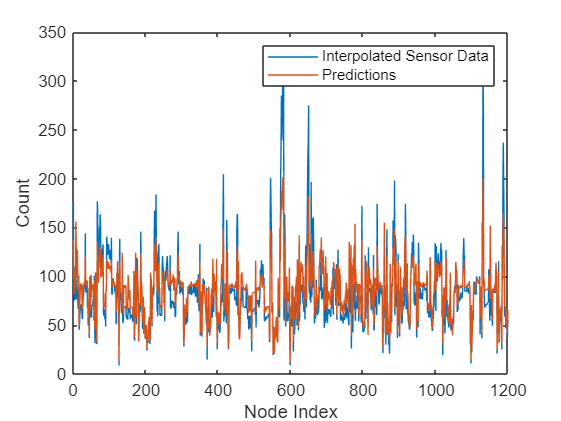


X_new = [degreeCentrality, closenessCentrality, betweennessCentrality, predi(171, :)', predi(170, :)', predi(121, :)'];
y_future_pred = predict(mdl, X_new); % Predict future counts
y_future_real = predi(172, :)';
figure;
plot(y_future_real)
hold on
plot(y_future_pred)
xlabel('Node Index')
ylabel('Count')
xlim([0 1200]);
legend('Interpolated Sensor Data', 'Predictions');

y_actual = predi(121, :)'; % Observed values
rmse = sqrt(mean((y_future_real - y_future_pred).^2)); % RMSE formula
disp(['RMSE: ', num2str(rmse)]);

RMSE: 18.8501
